# Plasma current controller

In this exercise we want to design a plasma current controller. The $I_p $ control is in charge of keeping the plasma current close to the desired values despite the action of external disturbances (such as additional heating systems) and model uncertainties (e.g. a wrong estimate of the plasma resistivity). Of course, the scenario currents are designed so as to keep $I_p $ close to its reference value during the shot, but in general all of the effects above are only approximately known in advance and hence a closed loop control action is needed.

Of course, we may start from the filamentary model discussed in the VS exercise and elaborate on it by letting the plasma current vary over time. However, here we will follow a slightly different approach, and save the discussion of a "simpler" model (with respect to the one we are using here) for later.

## Preliminaries and transformer currents pattern

As usual, we start by loading our plasma linearized model

addpath ./functions
addpath ./models
addpath ./data 

modelName = fullfile(pwd,'models','SOF@18d66s_FG.mat');
model = load(modelName);

lm.A = -model.L\model.R;
lm.B =  model.L\eye(size(model.L));
lm.C =  model.C;
lm.D =  zeros(size(lm.C,1), size(lm.B,2));
lm.E = -model.L\model.LE;
lm.F =  model.F;

Now, the key idea is to find a combination of PF currents capable of acting on the plasma current without affecting the plasma shape too much. 

**(Notice: for a diverted configuration, the plasma boundary is defined as the isoflux line passing through the X-point. )**

There are a few different ways to find this combination. The easiest one is to take a few plasma-wall gaps and find **a combination of currents which acts on **$I_p $** without changing the plasma-wall gaps**.

First we need to quantify the effect of the active currents on the plasma current. We could take the row of the C matrix associated to the plasma current

i_Ip = get_y_idx(model.y_type,'Ipl',1);
C_Ip = lm.C(i_Ip,:);

But since Ip is a state variable of our model, this matrix is just a bunch of zeros :(

C_Ip(:,1:10)

ans = 1.0e-11 *

    0.1112   -0.0248   -0.0292    0.0552    0.0754    0.0607   -0.0195   -0.0795   -0.0682   -0.4313


So, we need to find an alternative solution. Let's start from the circuit equations


$$L\dot{I}(t)+RI(t) = V(t)$$


We are only looking for the effect of the PF currents on $I_p$, so we'll make the following simplifying assumptions:

- neglect the effect of the resistivity on both the plasma (very hot) and the coils (superconductive), so $R_{PF} = 0, R_{Ip} \approx 0$

- neglect the effect of the eddy currents

Our circuit equations become


$$L_{PF}\dot{I}_{PF}(t)+M_{I_p2PF}\dot{I}_p(t)=V_{PF}(t) \\
M_{PF2I_p} \dot{I}_{PF}(t)(t)+L_{I_p}\dot{I}_p(t)=0$$


where the pedices are used to distinguish between the PF currents and the plasma current and the self and mutual inductance term are explicitly separated. 

From the second equation


$$dI_p \approx -\frac{M_{PF2I_p}}{L_{I_p} }dI_{PF}(t)$$


This is (approximately) the contribution of a variation of the PF currents on the plasma current we were looking for! So the matrix we need is

C_PF2Ip   = -model.L(end,1:10)/model.L(end,end);

then, we take the rows associated to a few gaps (as we did in exercise A)

% Get gaps definition
r_gap = model.Input_struct.r_sens_gap;
z_gap = model.Input_struct.z_sens_gap;
t_gap = model.Input_struct.theta_sens_gap_deg;

% add some more gaps
gaps = [1 5 7 9 11 16 17 18 19 29];
rg = r_gap(gaps);
zg = z_gap(gaps);
tg = t_gap(gaps);
lg = 1; 

% Gap C matrix
i_gap = get_y_idx(model.y_type,'Gap');
i_gap = i_gap(gaps);
C_gap = model.C(i_gap,:);

% X-point C matrix
i_xp = get_y_idx(model.y_type,{'Rbound','Zbound'},1);
C_xp = model.C(i_xp,:);

This is our choice of gaps

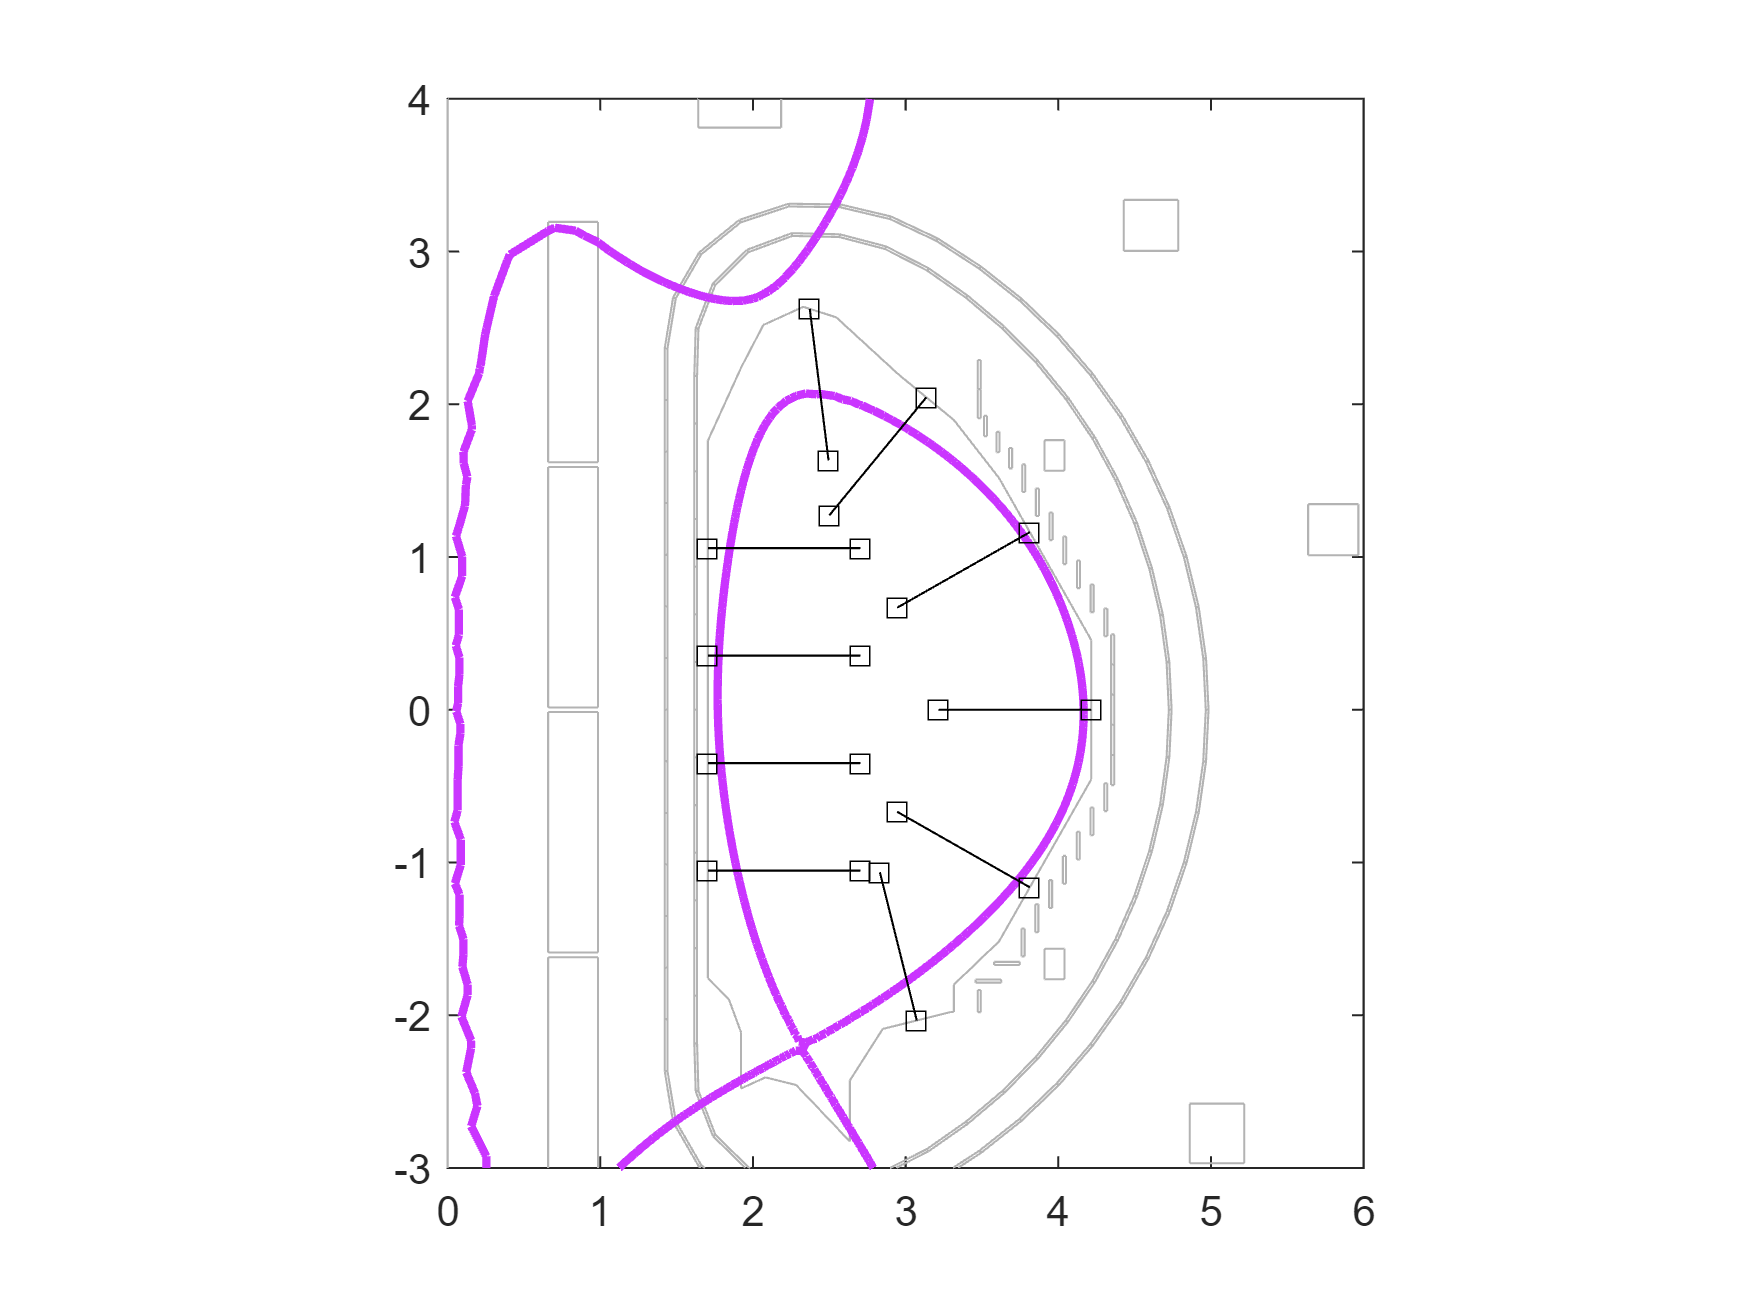

figure
nnodes = size(model.Input_struct.p,2);
psib = model.y_np(get_y_idx(model.y_type,'psb_c',1));
plot_mesh(model.Input_struct);
hold on
hb = plot_plasma(model.Input_struct, model.x_np(1:nnodes), psib*[1 1]);
set(hb,'linewidth',2)
hold on
xlim([0 6])
ylim([-3 4])

for i = 1 : numel(rg)
  plot([rg(i) rg(i)+lg*cosd(tg(i))], [zg(i) zg(i)+lg*sind(tg(i))],'sk-')
end

Now, to find our transformer current pattern, we can pseudo-invert the C matrix associated to the gaps and the plasma current so as to get a desired output combination

dIp  = 1;
dGap = zeros(numel(rg),1);

% C_It = [C_PF2Ip; 
%         C_gap(:,1:10);
%         C_xp(:,1:10)];

C_It = [C_PF2Ip; 
        C_gap(:,1:10)];

Itransf = C_It\[dIp; dGap];

% And normalize
Itransf = Itransf/norm(Itransf)

Itransf =    -0.4703
   -0.4363
   -0.4382
   -0.4649
   -0.0270
   -0.0124
   -0.3267
   -0.2642
    0.0383
   -0.0378


Finally, let's see what is the flux map generated on a plasmaless model by this pattern of currents. We will proceed as we did in the case of the VS.

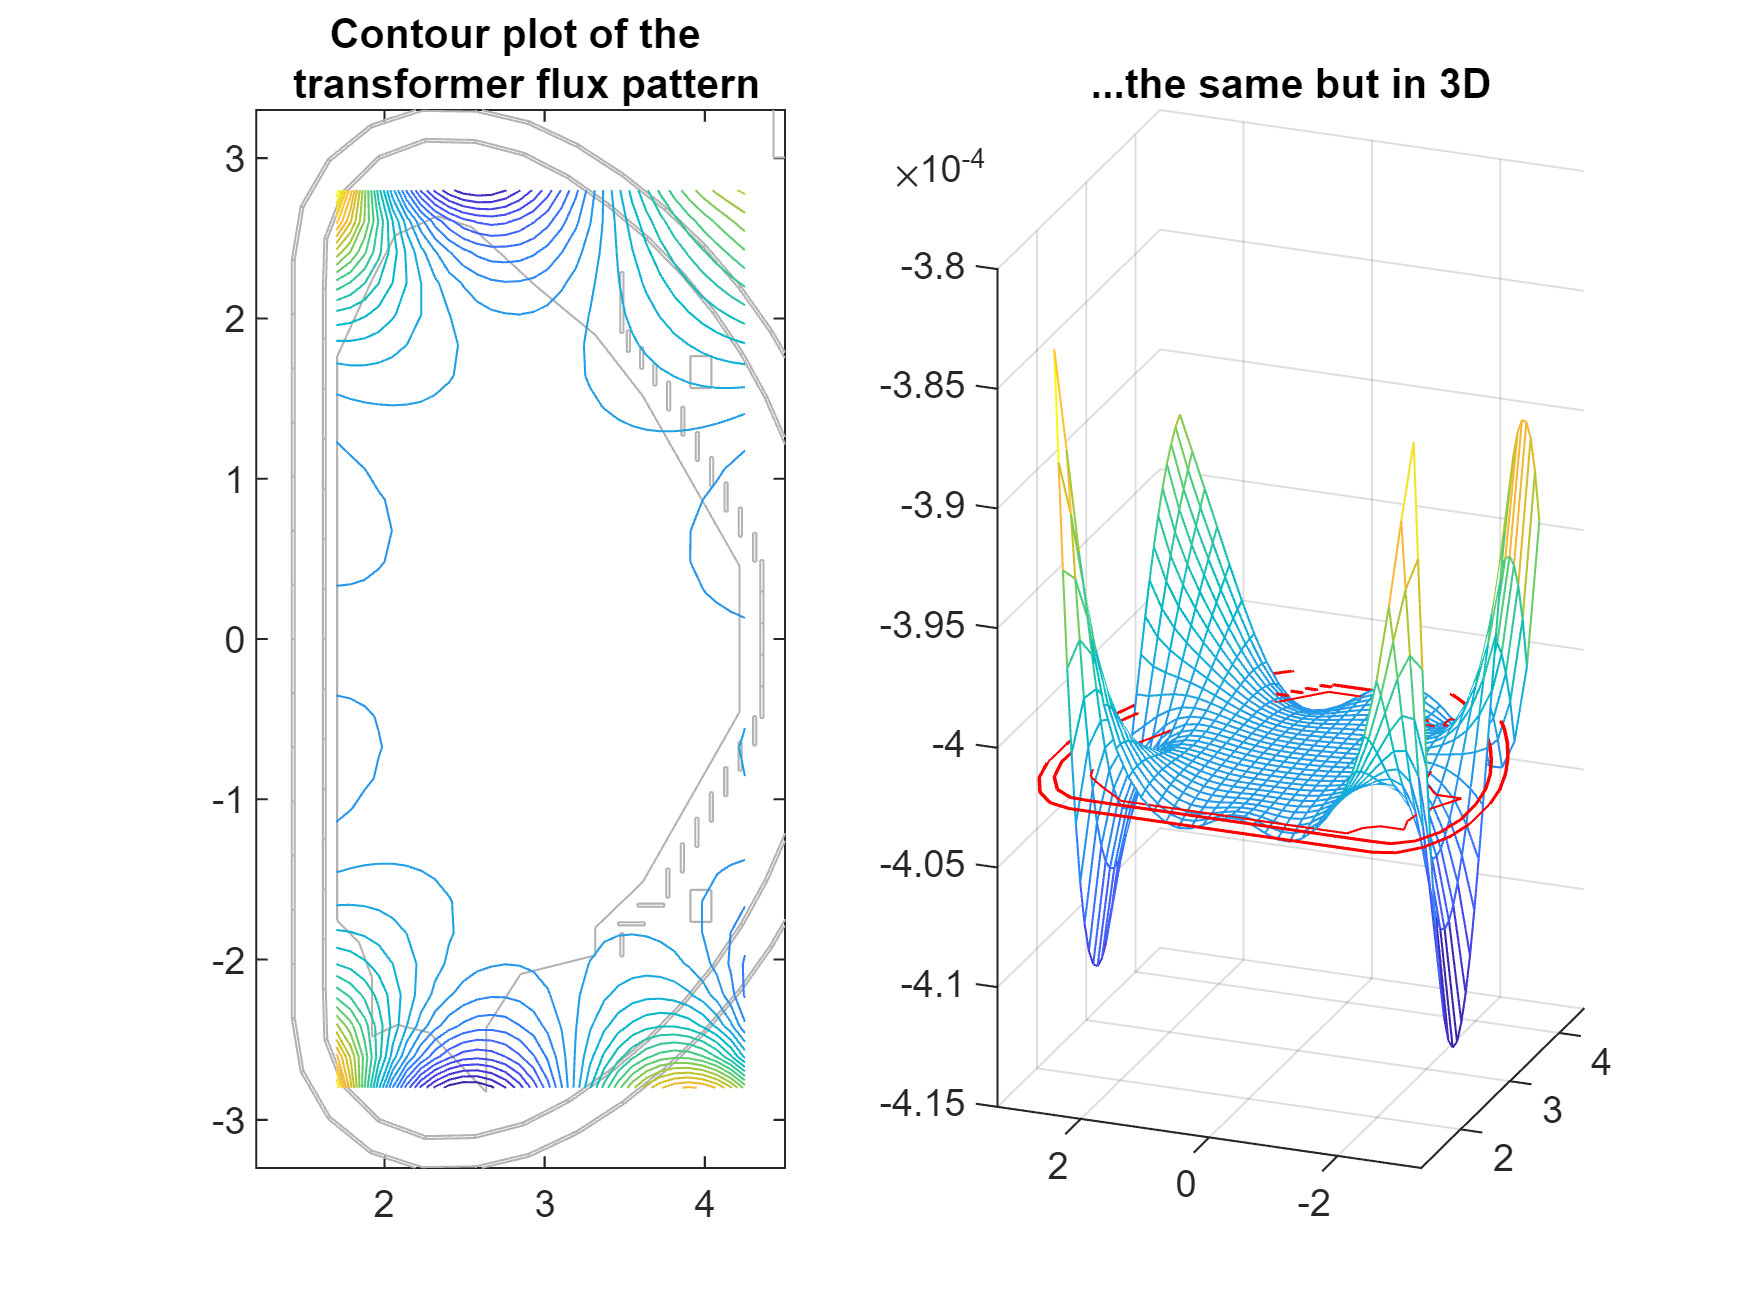

% Load plasmaless model
addpath ./functions
addpath ./models
addpath ./data 

plasmalessName = fullfile(pwd,'models','plasmaless_FG.mat');
plasmaless = load(plasmalessName);

% Compute ISO representation matrices
pm.A = -plasmaless.L\plasmaless.R;
pm.B = plasmaless.L\eye(size(plasmaless.L));
pm.C = plasmaless.C;
pm.D = zeros(size(pm.C,1), size(pm.B,2)); % just a bunch of zeros

% Apply transformer currents
dI = zeros(size(pm.C,2),1);
dI(1:10) = Itransf;

% Get output indexes in the linearized model
i_fg = get_y_idx(plasmaless.y_type,'Flux_grid');
n_fg = plasmaless.y_type(i_fg,1);
r_fg = plasmaless.Input_struct.r_sens(contains(plasmaless.Input_struct.names_sensors,n_fg));
z_fg = plasmaless.Input_struct.z_sens(contains(plasmaless.Input_struct.names_sensors,n_fg));

% Compute flux variation
C_fg = pm.C(i_fg,:);
dy   = C_fg*dI;

R_fg = reshape(r_fg,30,30);
Z_fg = reshape(z_fg,30,30);
dY   = reshape(dy,30,30);

figure
subplot(121)
hm = plot_mesh(plasmaless.Input_struct);
hold on
contour(R_fg,Z_fg,dY,31)
xlim([ 1.2 4.5])
ylim([-3.3 3.3])
title(sprintf('Contour plot of the \n transformer flux pattern'))

subplot(122)
mesh(R_fg,Z_fg,dY)
hold on
plot3(hm.XData,hm.YData,hm.XData*0+dY(end/2,end/2),'r')
view([-69 11.5])
xlim([ 1.2 4.5])
ylim([-3.3 3.3])
title('...the same but in 3D')

As you can see, the flux is almost flat inside the limiter. This is good news, as it means that this particular pattern should work also for different plasma configurations (even if we designed it based on a specific equilibrium). Remember that flux contours are iso-flux lines in the poloidal plane, so adding a **constant** flux does not modify the magnetic topology.

### Another take on the calculation transformer currents

Another possibility is to use our plasmaless model to design our transformer currents pattern.

To do so, we may take again our grid of virtual flux sensors and find a set of currents that produce approximately the same field in the central region of our grid.

We start by choosing the region where we want to have constant flux

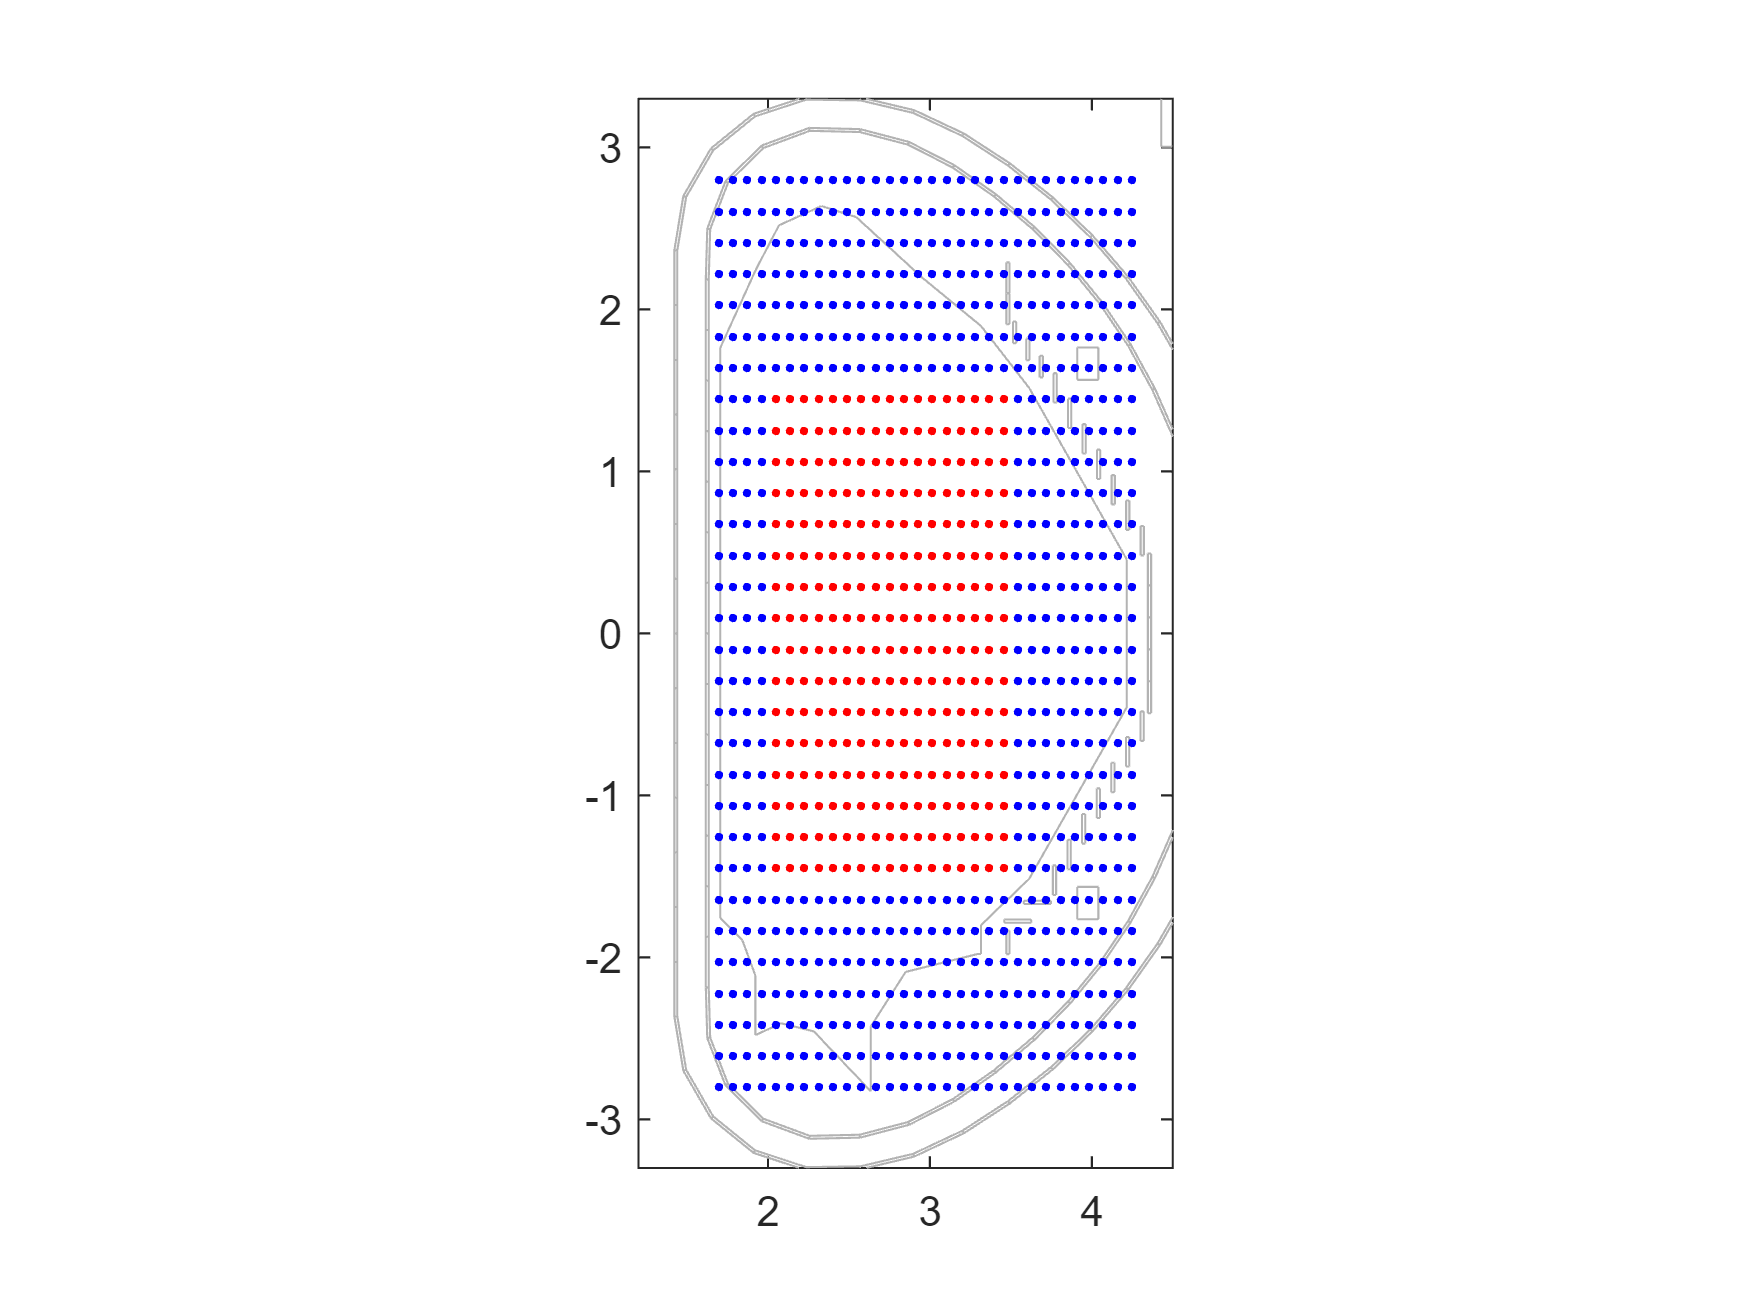

% For simplicity we use a rectangle in the center of the grid
zmin = -1.5;
zmax = +1.5;
rmin = 2;
rmax = 3.5;

% Here we get the logical index of the considered sensors in the '_fg'
% vectors and extract coordinates and indices in the full C matrix
ic = r_fg>rmin & r_fg<rmax &z_fg>zmin & z_fg<zmax;
rfg_c = r_fg(ic);
zfg_c = z_fg(ic);
ifg_c = i_fg(ic);

% Let's see where our sensors are placed
figure
plot_mesh(plasmaless.Input_struct);
hold on
plot(r_fg,z_fg,'.b')
plot(rfg_c,zfg_c,'.r')
xlim([ 1.2 4.5])
ylim([-3.3 3.3])

To compute our transformer currents, we extract the rows of the C matrix corresponding to our subset of virtual flux sensors and impose a constant flux variation in the considered region (let's call it $\delta \psi ^*$). We can then compute our transformer currents pattern $I_{transf}$ by pseudoinverting our $C$ matrix, i.e. 


$$I_{transf} = C^\dagger \delta \psi ^*$$


C1 = pm.C(ifg_c,1:10);
dpsi = -ones(size(C1,1),1); % the - sign is just to get the same direction as before

Itransf1 = C1 \ dpsi;
Itransf1 = Itransf1 / norm(Itransf1);

Let's check the result

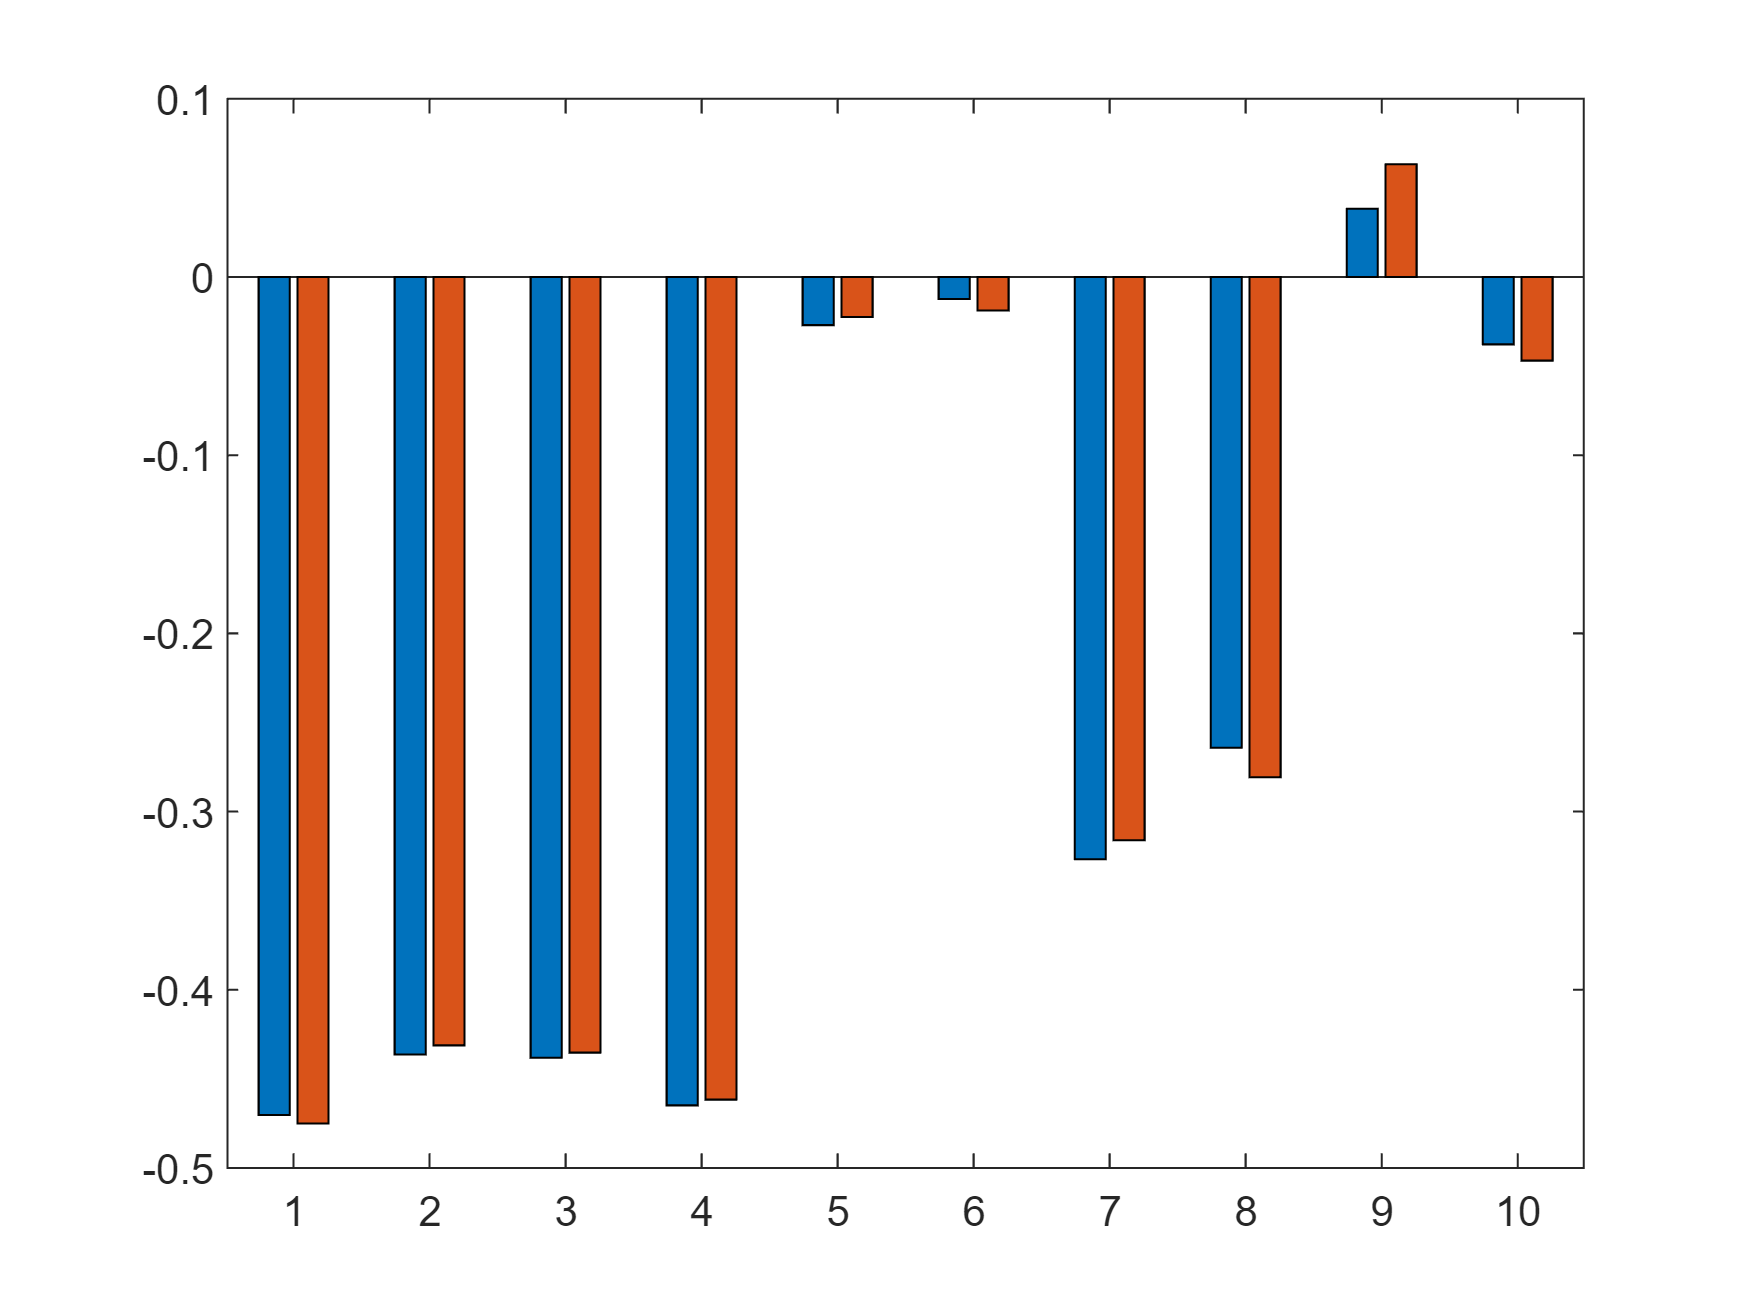

figure
bar([Itransf,Itransf1]);

The pattern we obtained is very similar to the one we have seen before. Let's also take a look at the flux map:

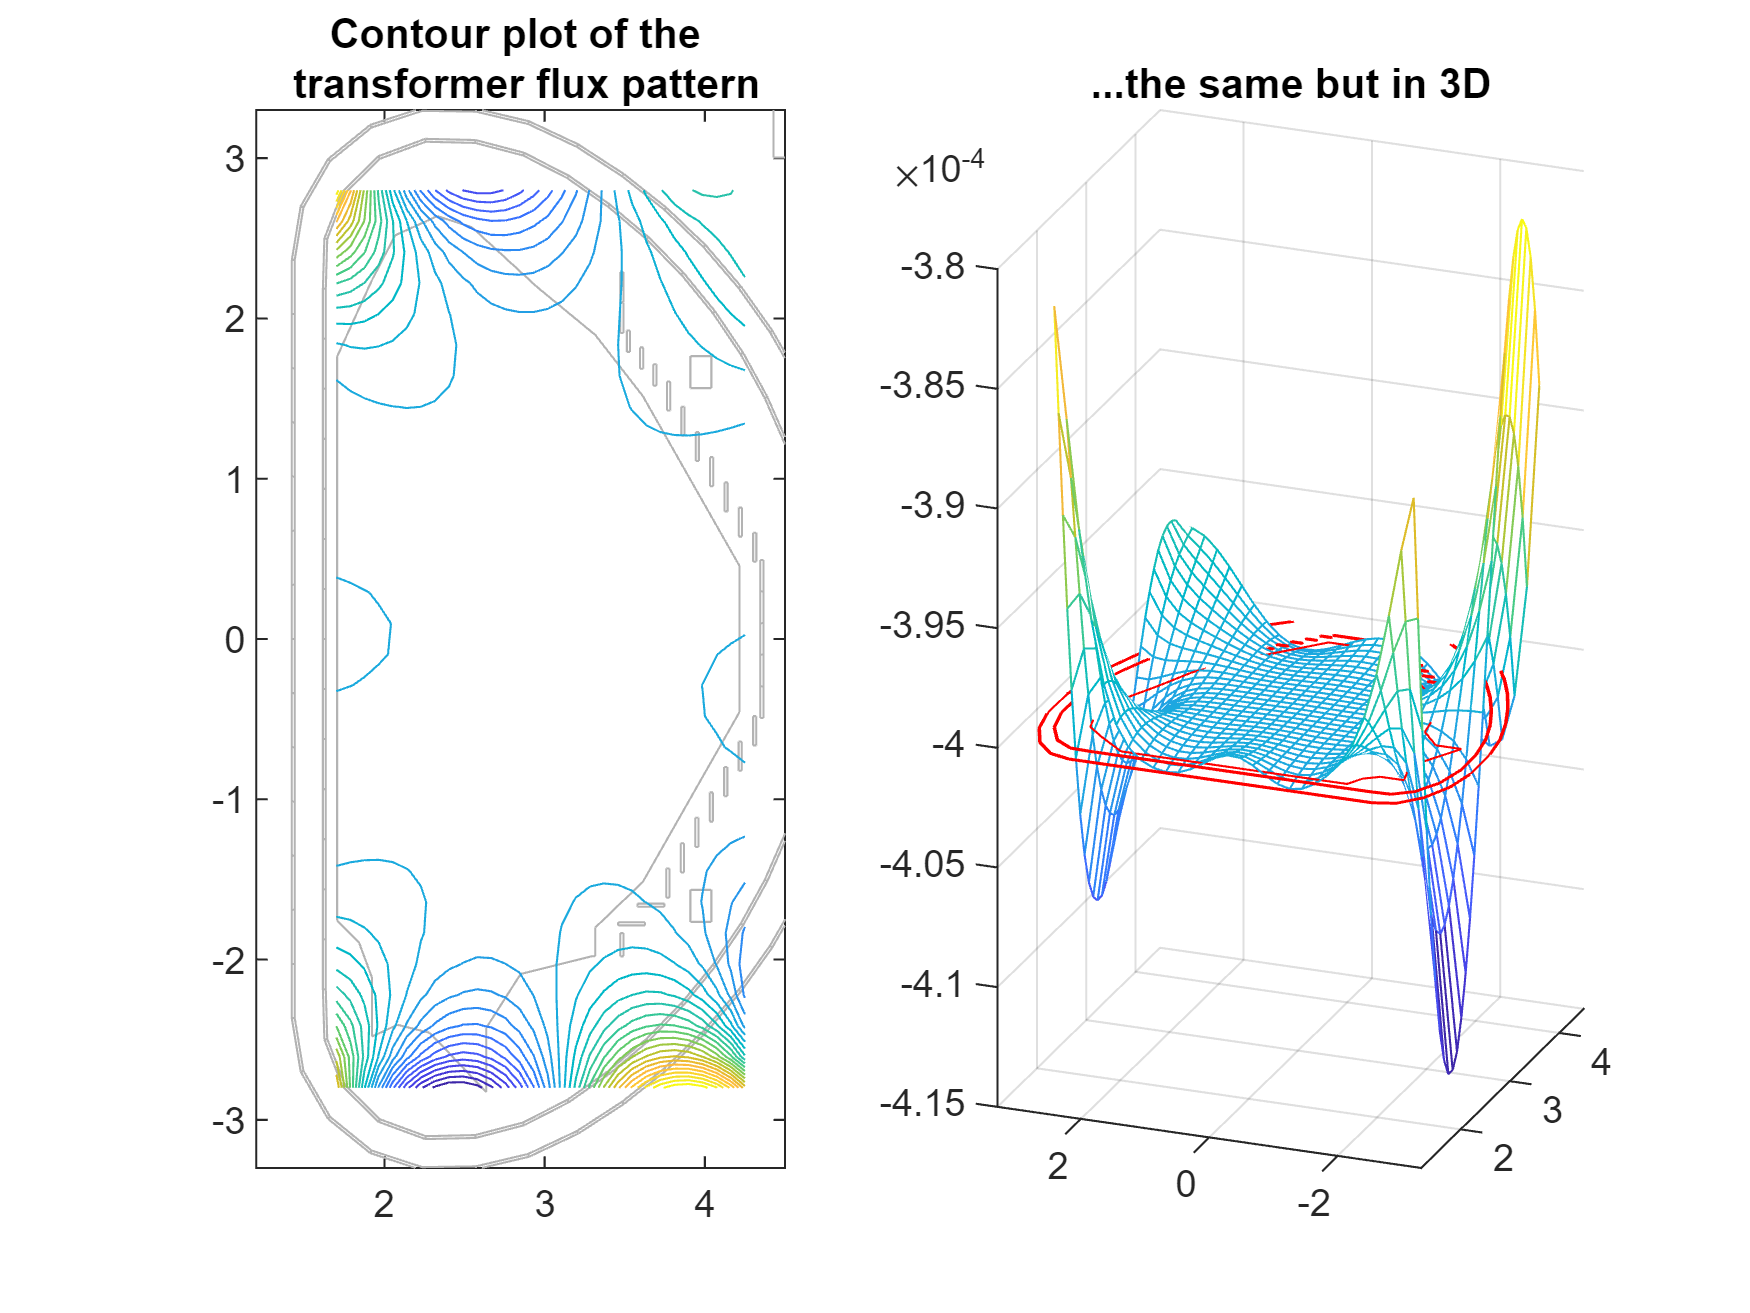

dy = C_fg(:,1:10)*Itransf1;
R_fg = reshape(r_fg,30,30);
Z_fg = reshape(z_fg,30,30);
dY   = reshape(dy,30,30);
figure
subplot(121)
hm = plot_mesh(plasmaless.Input_struct);
hold on
contour(R_fg,Z_fg,dY,31)
xlim([ 1.2 4.5])
ylim([-3.3 3.3])
title(sprintf('Contour plot of the \n transformer flux pattern'))
subplot(122)
mesh(R_fg,Z_fg,dY)
hold on
plot3(hm.XData,hm.YData,hm.XData*0+dY(end/2,end/2),'r')
view([-69 11.5])
xlim([ 1.2 4.5])
ylim([-3.3 3.3])
title('...the same but in 3D')

## Dynamic regulator design

What we've seen until now is just half of the story. In fact, usually we also add a dynamic regulator to our system! 

To tune our controller, we need to build our model. So, same old story; but this time we'll load a pre-made model (the one we saved in the previous exercise).

% Load ss model
load PF_contr.mat PF_clsys

% Change the output equation of the PFC closed-loop system
Ip_olsys = ss(PF_clsys.a,PF_clsys.b,lm.C(i_Ip,:),lm.D(i_Ip,1:10));

% Assign I/Os
Inames = model.y_type(1:10,1);
Ip_olsys.inputname  = Inames;
Ip_olsys.outputname = 'Ip';


This time, we'll use a PI controller. Without going into too much detail, just tune the controller with the pidtune matlab command. We can tune the controller on a SISO plant with the transformer current as input and the plasma current as output

Ip_contr = pidtune(Ip_olsys*Itransf,'PI',3) % last parameter is the desired crossing frequency, usually the plasma current controller is not too fast

Ip_contr =
 
        1 
  Ki * ---
        s 

  with Ki = 0.0243
 
Continuous-time I-only controller.



However, we'll keep the transformer current pattern in the Ip controller for later use

Ip_contr = Ip_contr*Itransf;
Ip_contr.inputname  = 'Ip';
Ip_contr.outputname = Inames

Ip_contr =
 
  From input "Ip" to output...
         -0.01143
   CS1:  --------
            s
 
         -0.01061
   CS2:  --------
            s
 
         -0.01065
   CS3:  --------
            s
 
         -0.0113
   CS4:  -------
            s
 
         -0.0006567
   EF1:  ----------
             s
 
         -0.0003009
   EF2:  ----------
             s
 
         -0.007944
   EF3:  ---------
             s
 
         -0.006424
   EF4:  ---------
             s
 
         0.0009311
   EF5:  ---------
             s
 
         -0.00092
   EF6:  --------
            s
 
Continuous-time transfer function.



Let's see how it works

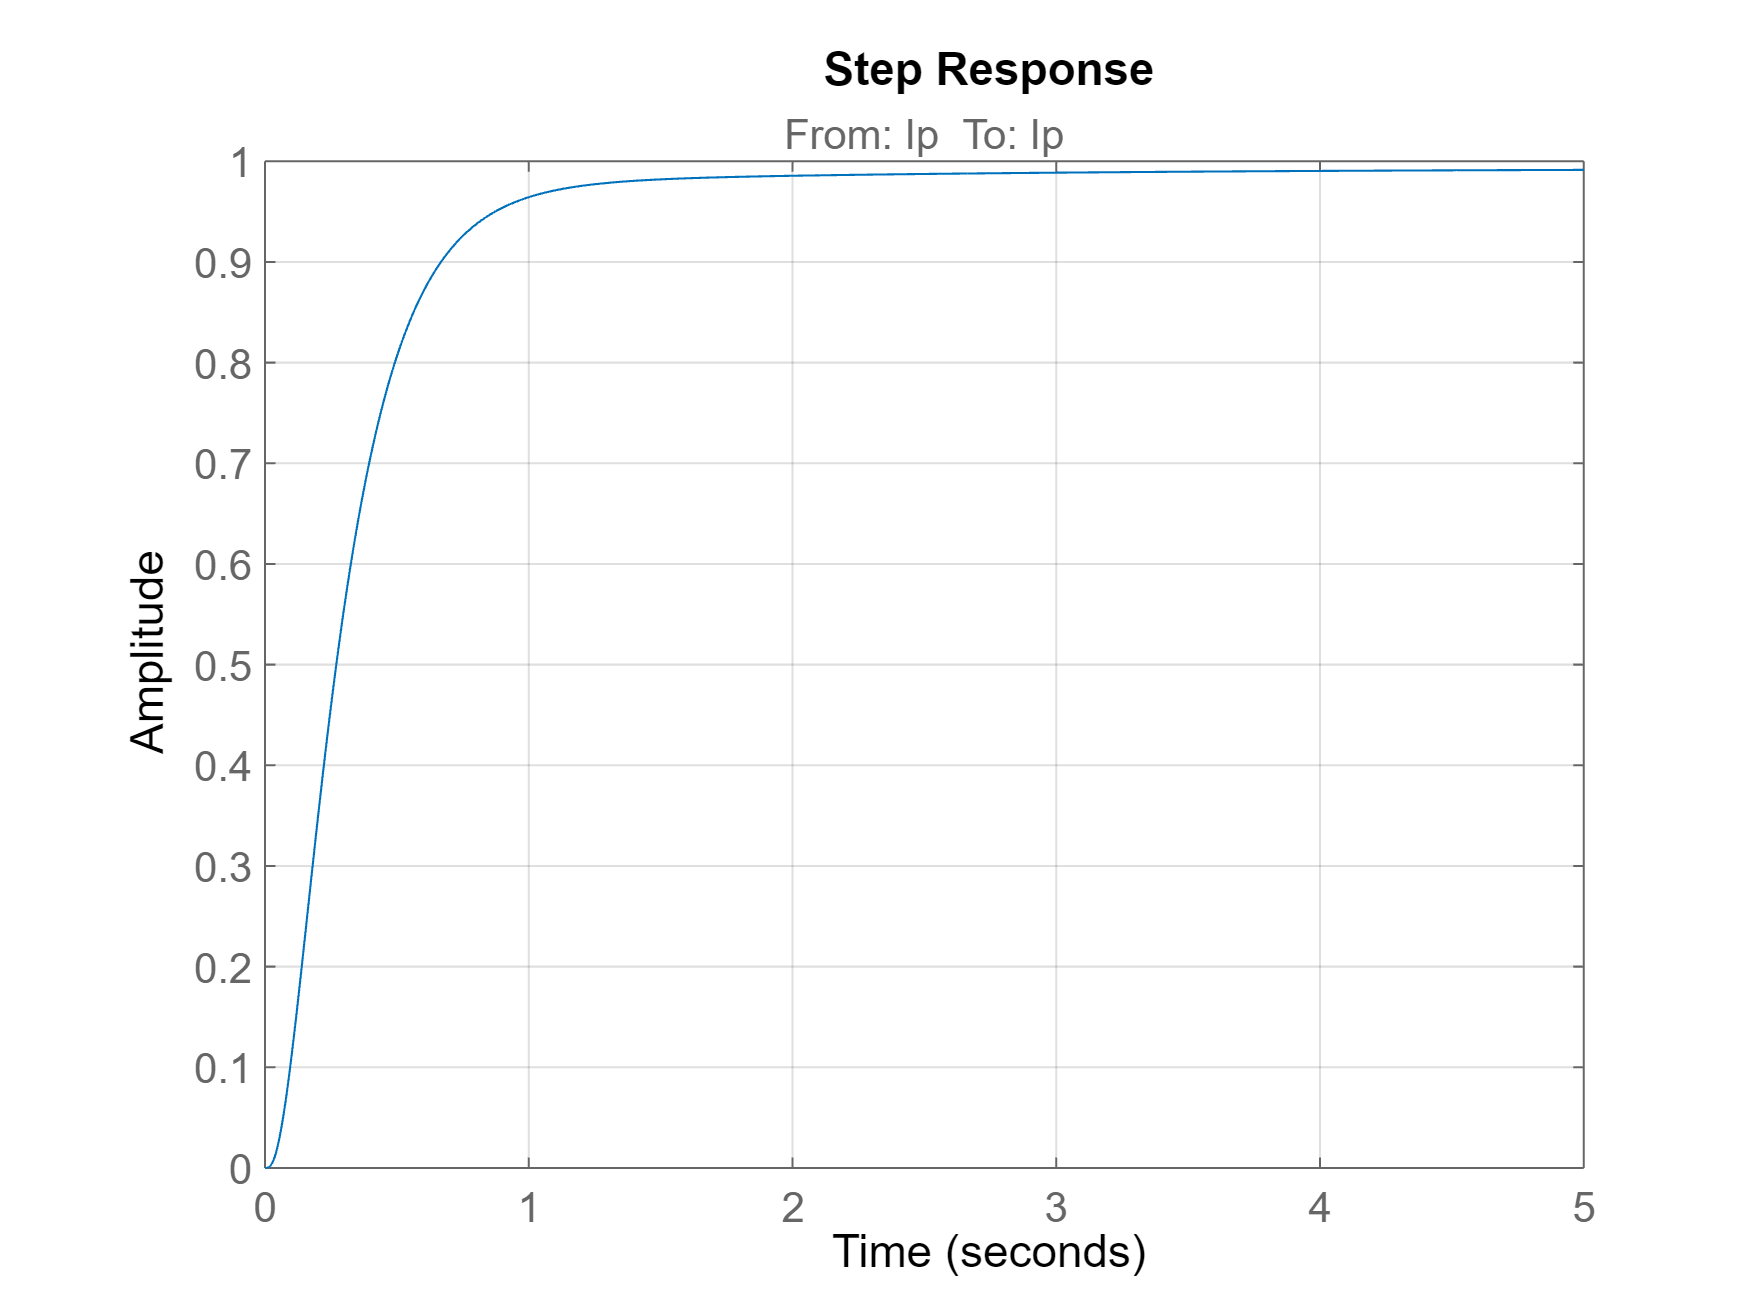

Ip_olsys = series(Ip_contr,Ip_olsys,'name');
Ip_clsys = feedback(Ip_olsys,1);
figure
step(Ip_clsys,0:1e-3:5), grid on

save ./data/Ip_contr Ip_contr Itransf Ip_clsys